% Read the image
img = imread("CNP.jpeg")

img = 217×232×3 uint8 array
img(:,:,1) =

   255   255   255   255   254   251   250   248   249   249   246   251   255   255   255   252   255   255   243   255   254   255   253   249   251   251   244   239   248   248   239   246   247   248   249   249   252   252   252   249   255   255   255   255   255   255   255   255   254   254   252   249   248   247   247   247   255   255   253   255   255   255   255   255   255   255   255   255   255   255   255   255   250   247   254   255   254   246   247   252   252   251   251   251   251   251   252   252   254   254   254   254   255   255   255   254   254   252   252   252   252   252   254   254   255   251   255   249   255   255   255   255   251   255   255   255   255   255   255   255   246   251   248   255   255   245   252   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   254   252   248   249   252   252   252   251   251   255   254   254   254   255   255   255   2

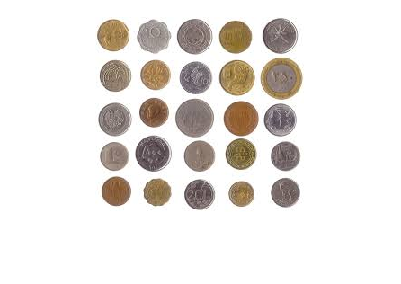

figure
imshow(img)


% Convert to grayscale
grayImg = rgb2gray(img)

grayImg = 217×232 uint8 matrix
   253   254   254   254   254   254   254   253   253   253   249   252   255   255   254   248   249   249   239   253   251   254   252   250   252   254   248   245   253   253   247   252   253   253   253   253   254   254   252   249   254   254   255   255   255   255   255   255   255   255
   253   254   254   254   255   253   254   254   246   254   254   255   252   248   250   252   253   252   250   252   252   254   253   254   254   254   254   252   254   252   252   253   252   253   253   254   254   255   255   255   254   254   254   255   255   255   255   255   254   255
   254   254   254   254   254   254   254   254   247   253   252   248   254   253   252   243   235   226   210   197   192   200   216   228   244   250   249   252   254   254   247   246   253   253   252   253   254   255   255   255   254   254   254   255   255   255   254   255   254   255
   254   254   254   254   254   254   253   253   246   254   254

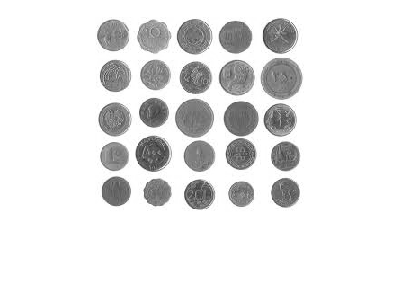

figure
imshow(grayImg)


% Apply Gaussian filter to smooth the image
filteredImg = imgaussfilt(grayImg, 2)

filteredImg = 217×232 uint8 matrix
   254   254   254   254   254   254   253   253   252   252   251   250   248   246   243   240   238   236   235   235   235   236   238   239   241   243   245   247   249   250   251   251   252   253   253   253   253   253   253   253   254   254   254   255   255   255   255   255   254   254
   254   254   254   254   254   254   253   252   251   250   248   245   241   236   232   228   224   222   220   220   220   221   223   225   229   233   237   241   244   247   249   251   252   252   253   253   253   253   253   254   254   254   254   255   255   255   255   255   254   254
   254   254   254   254   254   253   252   251   248   245   240   234   228   221   214   209   205   203   201   201   201   202   204   207   211   217   223   229   235   241   245   248   250   252   253   253   253   253   253   254   254   254   254   255   255   255   255   254   254   254
   254   254   254   254   253   252   251   247   242   236  

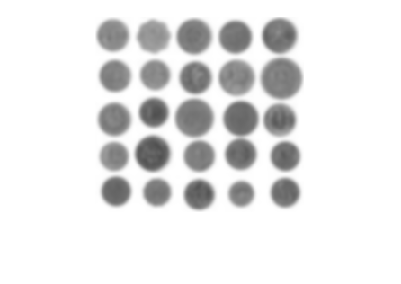

figure
imshow(filteredImg)



% Convert to binary image using Otsu’s thresholding method
bw = imbinarize(filteredImg)

bw = 217×232 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

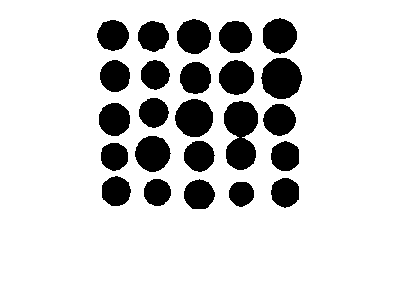

figure
imshow(bw)

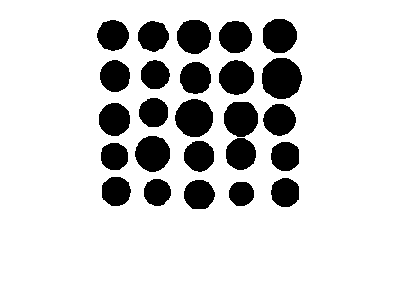


% Smooth the coin boundaries
se = strel('disk', 5);
bw = imclose(bw, se);
imshow(bw)

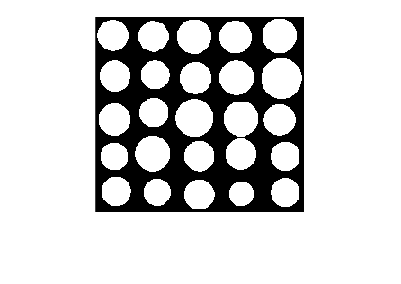


% Invert the binary image
bw = ~bw;
imshow(bw)



% Fill holes in the binary image
bw = imfill(bw,"holes")

bw = 217×232 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

imshow(bw)


% Remove small objects that are not coins
bw = bwareaopen(bw, 100);
imshow(bw)

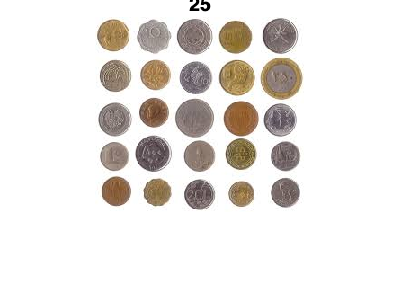


% Label the connected components in a 2-D binary image
[labeledImage, numCoins] = bwlabel(bw);

figure;
imshow(img);
title(["Number of coins", num2str(numCoins)]);

disp(num2str(numCoins))

25
